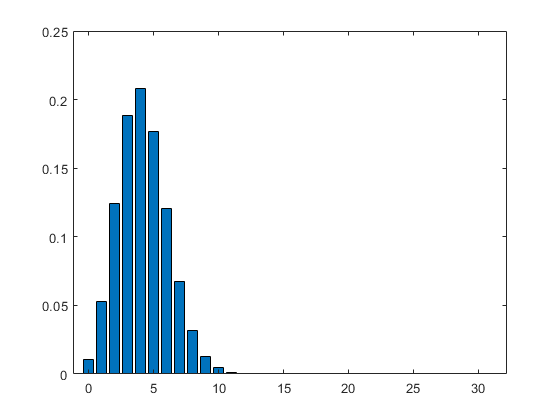

format long

%Distribution for the binomial for the probability of getting the same
%hamming weight in various parts
N = 31;
psame = 0.1360;
k = 0 : 31;
y = binopdf(k,N,psame);

bar(k,y)

**Now, we know that for the threshold we set for euclidean distance, there is a probability of**

truePosProb = 0.5

truePosProb = 0.5000

falsePosProb = 0.2139

falsePosProb = 0.2139

Graph the distribution for two equal operands. Then the probability is the true pos prob

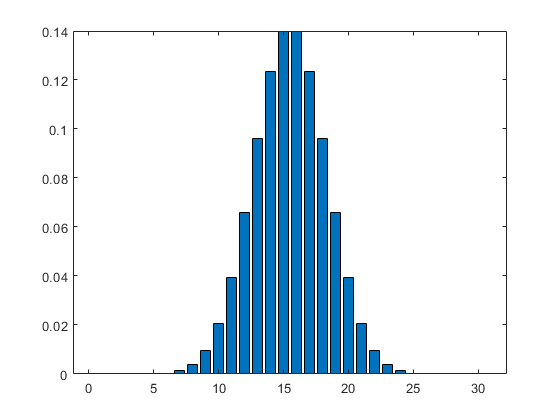

N = 31;
ytrue = binopdf(k,N,truePosProb);
bar(k,ytrue)

What is the probability of getting a one for a random operator? Probability of getting a one and classifying it well plus the probability of getting a 0 and classifying it badly. Therefore it is

prandom = psame * truePosProb + (1 - psame) * falsePosProb

prandom = 0.2528

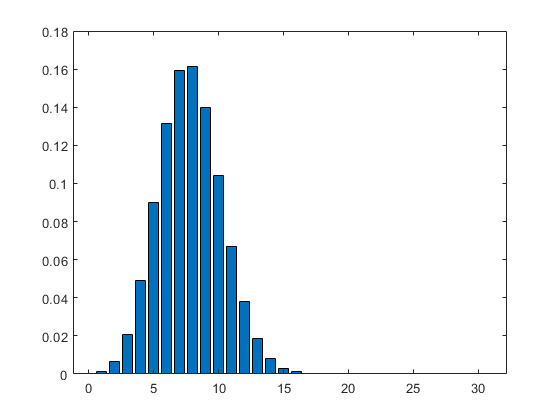

yrandom = binopdf(k,N,prandom);
bar(k,yrandom)

 Overlay both graphs

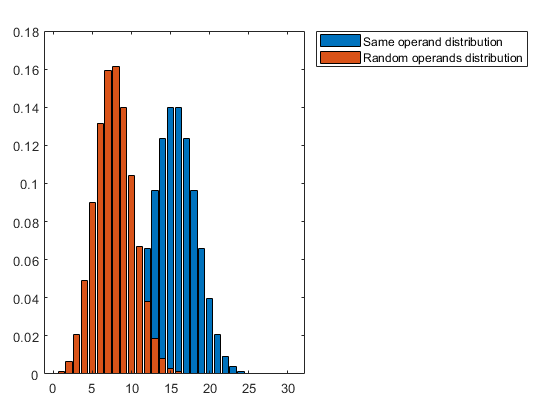

bar(k,ytrue)
hold on
bar(k,yrandom)
hold off
legend("Same operand distribution","Random operands distribution","Location","bestoutside")

Maximum likelihood, from which value ?

value = k(find(ytrue >= yrandom,1))

value = 12

In that value the probability in distribution for same operand is

ytrue(k==value)

ans = 0.0657

In the other distribution it is

yrandom(k==value)

ans = 0.0379

The cumulative probability for the most probable values (7,8,9) for random distribution is

yrandom(8)+yrandom(9)+yrandom(10)

ans = 0.4604

The cumulative probability for the most probable values (15,16,17) for same operand distribution is

ytrue(16)+ytrue(17)+ytrue(18)

ans = 0.4034

We can define the probability of getting a false positive as the cumulative probability in the random distribution such that P(k >= 14)

probTotalFalsePositive = sum(yrandom(find(ytrue >= yrandom,1):end))

probTotalFalsePositive = 0.0693

Likewise, the probability of getting a true positive will be the cumulative probability in the same operand distribution such that P(k>=14)

probTotalTruePositive = sum(ytrue(find(ytrue >= yrandom,1):end))

probTotalTruePositive = 0.9252

Supposing that ones are uniformly distributed in a key, then the number of positives will be the same as the number of negatives. Therefore, one can estimate the accuracy as (TP + FP) / (P + N) = TP + FP/(2P)= TP/2P + FP / 2N = TPrate/2 + (1-FPrate)/2

supposedAccuracy = probTotalTruePositive/2 + (1-probTotalFalsePositive)/2

supposedAccuracy = 0.9279

So 80.46% of accuracy. Is it enough ?

Remember we are working with P-521. That means that we have mean errors of

bitErrors = 521*(1-supposedAccuracy)

bitErrors = 37.5524

The paper from Hanley explains that the Stinson algorithm can be used to derive the key with a t-bit error in a n-bit hypothesis and they define their threshold of cost with 2^54 for practical and 2^40 for trivial. This leads to a cost of

cost = 0;
n2 = ceil(521/2);
for i = 1 : ceil(bitErrors/2)
    cost = cost + nchoosek(n2,i);
end

cost = cost * 521

cost = 1.9570e+31

Which is equivalent to 2^ to the 

exponent = log2(double(cost))

exponent = 103.9484

Can we calculate the ROC for our classfier? 

% XFull24 = zeros(size(X24));
% YFull24 = zeros(size(Y24));
% indexes = zeros(size(X24));
% N = 31;
% k = 0:31;
% count = 0;
% 
% for i = 1 : length(X24)
%     distTrue = makedist("Binomial","N",31,"p",Y24(i));
%     pdftrue = pdf(distTrue,0:31);
%     prandom = psame * Y11(i) + (1 - psame) * X24(i);
%     distRandom = makedist("Binomial","N",31,"p",prandom);
%     pdfrandom = pdf(distRandom,0:31);
%     if distTrue.mean > distRandom.mean %Don't take into account the cases where the mean of the true distribution is lower than random distribution
%         count = count + 1;
%         index = find(pdftrue >= prandom,1);
%         XFull24(count) = sum(pdfrandom(index:end));
%         YFull24(count) = sum(pdftrue(index:end));
%         indexes(count) = i;
%     end
% end
% XFull24 = XFull24(1:count);
% YFull24 = YFull24(1:count);
% indexes = indexes(1:count);
% 

% 
% plot(XFull24,YFull24)
% title("ROC for full clasifier with max traces and euclidean distance")
% xlabel("False positive rate")
% ylabel("True positive rate")

We can try to maximize accuracy

% accVector = (1-XFull24)/2 + YFull24/2;
% [val,ind] = max(accVector)

Now calculate the cost again

% supposedAccuracy = val;
% 
% bitErrors = 521*(1-supposedAccuracy)
% 
% cost = 0;
% n2 = ceil(521/2);
% for i = 1 : ceil(bitErrors/2)
%     cost = cost + nchoosek(n2,i);
% end
% cost = cost * 521; 

Which is equivalent to 2^ to the 

% exponent = log2(double(cost))

Idea : Choose classifier that has the biggest accuracy

%falsePosCell = {X11 X12 X13 X14 X15 X16 X17 X18 X21 X22 X23 X24 X25 X26 X27 X28}
%truePosCell = {Y11 Y12 Y13 Y14 Y15 Y16 Y17 Y18 Y21 Y22 Y23 Y24 Y25 Y26 Y27 Y28}
falsePosCell = {X21}

falsePosCell = 1×1 cell array
    {498795×1 double}


truePosCell = {Y21}

truePosCell = 1×1 cell array
    {498795×1 double}



selectedPoints = zeros(16,5); %False pos, true pos, total accuracy, total false positive, total true positive
%Get the best point for each one of them
for i = 1 : length(falsePosCell)
    falsePosVect = cell2mat(falsePosCell(i));
    truePosVect = cell2mat(truePosCell(i));
    for j = 1 : length(falsePosVect)
        distTrue = makedist("Binomial","N",31,"p",truePosVect(j));
        prandom = psame * truePosVect(j) + (1 - psame) * falsePosVect(j);
        distRandom = makedist("Binomial","N",31,"p",prandom);
         if abs(distTrue.mean - distRandom.mean) > 0
            pdftrue = distTrue.pdf(k);
            pdfrandom = distRandom.pdf(k);
            threshold = k(find(pdftrue >= pdfrandom,1));
            probTotalFalsePositive = sum(pdfrandom(threshold+1:end));
            probTotalTruePositive = sum(pdftrue(threshold+1:end));
            supposedAccuracy = probTotalTruePositive/2 + (1-probTotalFalsePositive)/2;
            if (supposedAccuracy>selectedPoints(i,3))
                selectedPoints(i,3) = supposedAccuracy;
                selectedPoints(i,1) = falsePosVect(j);
                selectedPoints(i,2) = truePosVect(j);
                selectedPoints(i,4) = probTotalFalsePositive;
                selectedPoints(i,5) = probTotalTruePositive;
            end
         end
    end
end
clear falsePosCell truePosCell distTrue prandom distRandom pdftrue pdfrandom threshold probTotalTruePositive probTotalFalsePositive supposedAccuracy

Display optimal points for each classifier, their accuracy and total values for false positive rate and true positive rate

for i = 1 : 16
    fprintf("Classifier %d",i);
    selectedPoints(i,1)
    selectedPoints(i,2)
    selectedPoints(i,3)
    selectedPoints(i,4)
    selectedPoints(i,5)
end

Classifier 1

ans =    0.079780361757106


ans =    0.331717618478029


ans =    0.936765734095301


ans =    0.056299283890626


ans =    0.929830752081228


Classifier 2

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 3

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 4

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 5

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 6

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 7

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 8

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 9

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 10

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 11

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 12

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 13

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 14

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 15

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Classifier 16

ans =      0


ans =      0


ans =      0


ans =      0


ans =      0


Which is the best classifier

[val,ind] = max(selectedPoints(:,3))

val =    0.936765734095301


ind =      1


Analysis of best classifier

ytrue = binopdf(k,N,selectedPoints(ind,2));
prandom = psame * selectedPoints(ind,2) + (1 - psame) * selectedPoints(ind,1)

prandom =    0.114043828671151


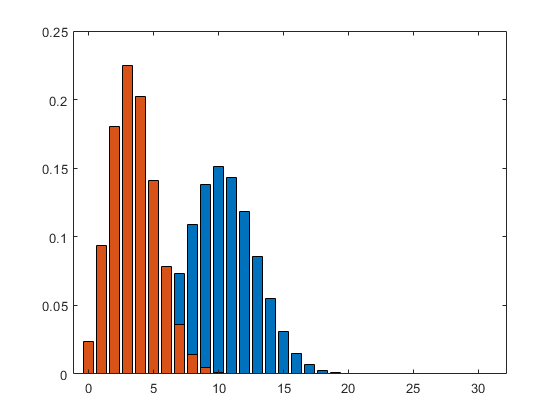

yrandom = binopdf(k,N,prandom);
bar(k,ytrue)
hold on
bar(k,yrandom)
hold off

selectedPoints(ind,3)

ans =    0.936765734095301


selectedPoints(ind,4)

ans =    0.056299283890626


selectedPoints(ind,5)

ans =    0.929830752081228



k(find(ytrue >= yrandom,1))

ans =      7


Which gives us

bitErrors = 521*(1-selectedPoints(ind,3))

bitErrors =   30.085443226036649


cost = 0;
n2 = ceil(521/2);
for i = 1 : ceil(bitErrors/2)
    cost = cost + nchoosek(n2,i);
end

cost = cost * 521

cost =      7.722994132900564e+27


Which is equivalent to 2^ to the 

exponent = log2(double(cost))

exponent =   92.641218837333071
